# **Read, Process, and Save an Image**

**Available on **[**GitHub**](https://github.com/z3301/DigImgProc_01)** and **[**MATLAB File Exchange**](https://www.mathworks.com/matlabcentral/fileexchange/123920-digital-image-processing-assignment-1)

### **Read an Image**

This code reads a list of image file names into the workspace as a 1D array of strings.  It then allows dropdown selection from that list to read the selected image file into the workspace as 3D array of integer color data.  The semi-colons at the ends of the lines prevent these elemts from being displayed.

Select an image from the dropdown:

images = ["strawberries.jpg","colorCheckerTestImage.jpg","lighthouse.png"];
imageSel = images(3);
imread(imageSel);
imageSel = ans;

### **Display the Image**

This code displays the image, rather than the array.

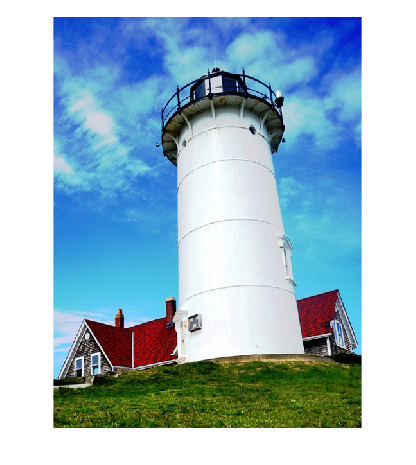

imshow(imageSel)

### Process the Image

This code applies a contrast filter to the image and creates a new image as a new 3d array in the workspace. The first three sliders allow adjustment of the low RGB limits and the last three sliders allow the adjustment of the high RGB limits.  The low values must be lower than the high values.

imageNew = imadjust(imageSel,[ ...
    % LOW IN RGB TRIPLET
    0.23 ...
    0.3 ...
    0.5 ...
    ; ... 
    % HIGH IN RGB TRIPLET
    0.8 ...
    0.51 ...
    0.59...
    ],[]);

### Display the New Image

This code displays the new image.

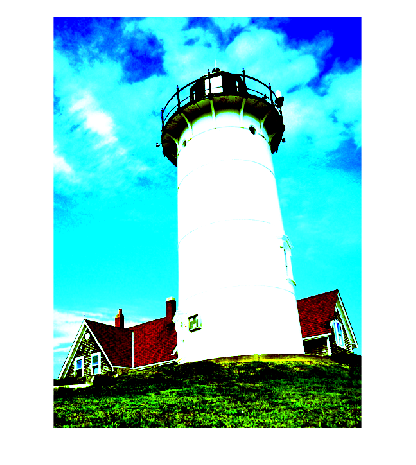

imshow(imageNew)

### Save the New Image

This code saves the new image as a new file in the same directory as this script.

Select a file format from the dropdown and click "Run":

formats = ["png","jpg","tif"];
format = formats(1);
imwrite(imageNew, "imageNew." + format)

 